## **Driver test program to check Clothoids library**

**Test circle**

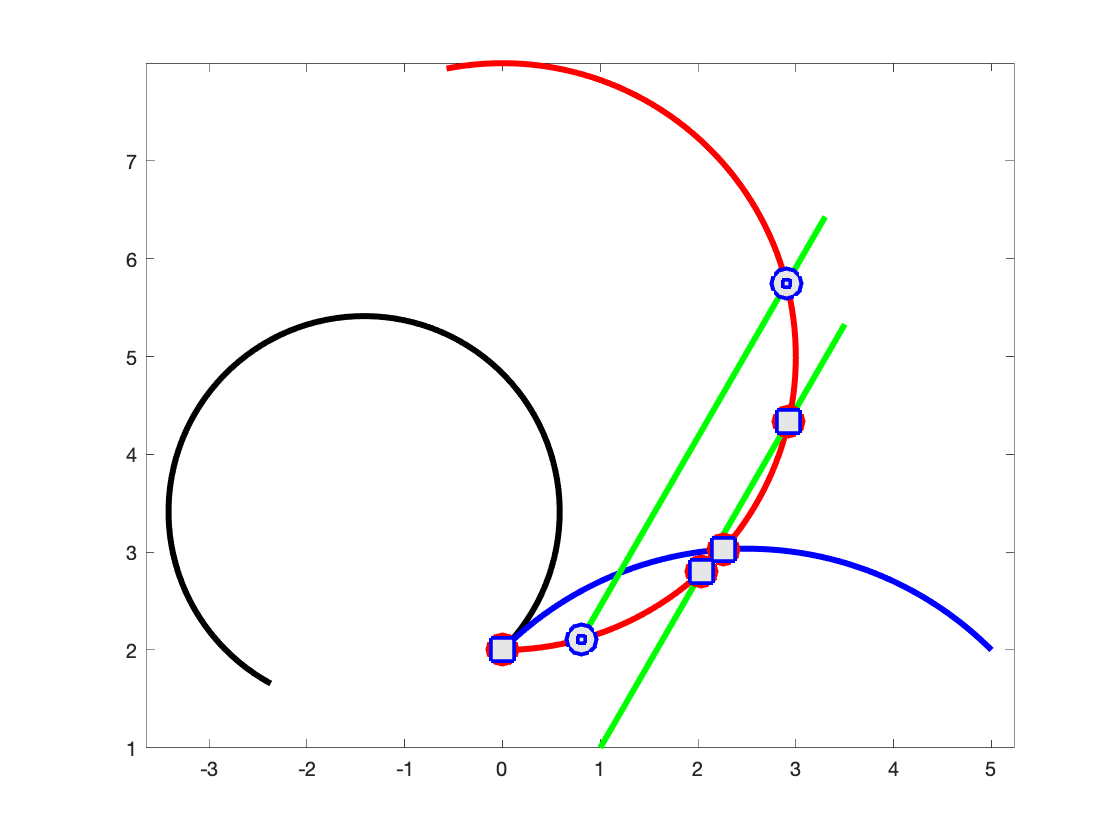

close all

% check constructors
x0     = 0;
y0     = 2;
x1     = 3;
y1     = 3;
x2     = 5;
y2     = 2;
theta0 = 0;
L      = 10;
k0     = 1/3;
L1 = CircleArc( x0, y0, theta0, k0, L );
L2 = CircleArc( x0, y0, theta0+pi/4, 1.5*k0, L );
L3 = CircleArc();
L3.build_3P(x0, y0, x1,   y1, x2, y2 );
L4 = LineSegment( x0+1,   y0-1, pi/3, 5 );
L5 = LineSegment( x0+0.8, y0+0.1, pi/3, 5 );
%
fmt1 = {'Color','red','Linewidth',3};
fmt2 = {'Color','black','Linewidth',3};
fmt3 = {'Color','blue','Linewidth',3};
fmt4 = {'Color','green','Linewidth',3};

L1.plot(100,fmt1);
hold on;
L2.plot(100,fmt2);
L3.plot(100,fmt3);
L4.plot(fmt4{:});
L5.plot(fmt4{:});

if true

[s1,s2] = L1.intersect(L2);

XY1 = L1.eval( s1 );
XY2 = L2.eval( s2 );

plot( XY1(1,:), XY1(2,:), 'o', ...
      'LineWidth',2,...
      'MarkerSize',15,...
      'MarkerEdgeColor','red',...
      'MarkerFaceColor',[0.9,0.9,0.9]);
plot( XY2(1,:), XY2(2,:), 's', ...
      'LineWidth',2,...
      'MarkerSize',15,...
      'MarkerEdgeColor','blue',...
      'MarkerFaceColor',[0.9,0.9,0.9] );
  
end

if true

[s1,s3] = L1.intersect(L3);

XY1 = L1.eval( s1 );
XY3 = L3.eval( s3 );

plot( XY1(1,:), XY1(2,:), 'o', ...
      'LineWidth',2,...
      'MarkerSize',15,...
      'MarkerEdgeColor','red',...
      'MarkerFaceColor',[0.9,0.9,0.9] );
plot( XY3(1,:), XY3(2,:), 's', ...
      'LineWidth',2,...
      'MarkerSize',15,...
      'MarkerEdgeColor','blue',...
      'MarkerFaceColor',[0.9,0.9,0.9] );

end

if true

%[s1,s4] = L1.intersect(L4);
[s4,s1] = L4.intersect(L1);

XY1 = L1.eval( s1 );
XY4 = L4.eval( s4 );

plot( XY1(1,:), XY1(2,:), 'o', ...
      'LineWidth',2,...
      'MarkerSize',15,...
      'MarkerEdgeColor','red',...
      'MarkerFaceColor',[0.9,0.9,0.9] );
plot( XY4(1,:), XY4(2,:), 's', ...
      'LineWidth',2,...
      'MarkerSize',15,...
      'MarkerEdgeColor','blue',...
      'MarkerFaceColor',[0.9,0.9,0.9] );
end

if true
    
[s1,s5] = L1.intersect(L5);

XY5 = L5.eval( s5 );
XY1 = L1.eval( s1 );

plot( XY5(1,:), XY5(2,:), 'o', ...
      'LineWidth',2,...
      'MarkerSize',15,...
      'MarkerEdgeColor','blue',...
      'MarkerFaceColor',[0.9,0.9,0.9] );
plot( XY1(1,:), XY1(2,:), 's', ...
      'LineWidth',2,...
      'MarkerSize',5,...
      'MarkerEdgeColor','b',...
      'MarkerFaceColor',[0.9,0.9,0.9] );
end

axis equal;

%